clear mypi;
clear;
mypi=raspi("192.168.86.100","Kollis","646djohr");

system(mypi,'lab4/./radar_sampler 31250 /home/Kollis/lab4/SAMPLE.bin','sudo');
getFile(mypi,'/home/Kollis/lab4/SAMPLE.bin','C:\GitHub\TTT4280-Sensorer\Lab4');
deleteFile(mypi, '/home/Kollis/lab4/SAMPLE.bin');

channels=2;
nBits=12;
VDD=3.3;
f_radar=24.13*10^9;
c=3*10^8;
N_fft=2^(16);
j=sqrt(-1);

fid=fopen("SAMPLE.bin","rb");
nomPeriod=fread(fid,1,"double");
nomPeriod = nomPeriod * 1e-6;
data=fread(fid,"uint16");
nSamples=numel(data)/channels; 
fs=1/nomPeriod;
dataMatrix = reshape(data,channels,nSamples);
fclose(fid);

h=transpose(hann(nSamples));
I=(dataMatrix(1,:))*VDD/(2.^nBits);
Q=(dataMatrix(2,:))*VDD/(2.^nBits);
I=I-mean(I);
Q=Q-mean(Q);

x=h.*(I+j*Q);
x=highpass(x,10,fs);
X=abs(fftshift(fft(x,N_fft)));
S=20*log10(X);
f=1/(N_fft*nomPeriod)*(-N_fft/2:N_fft/2-1);

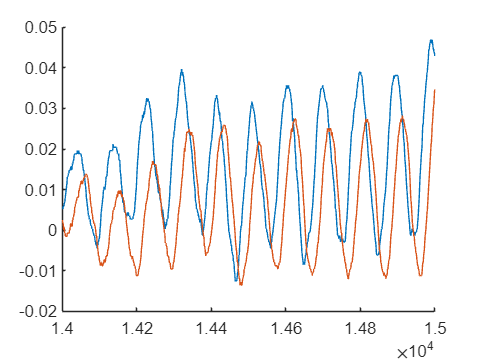

figure;
hold on; 
plot(I);
plot(Q);

xlim([14000 15000]);
hold off;

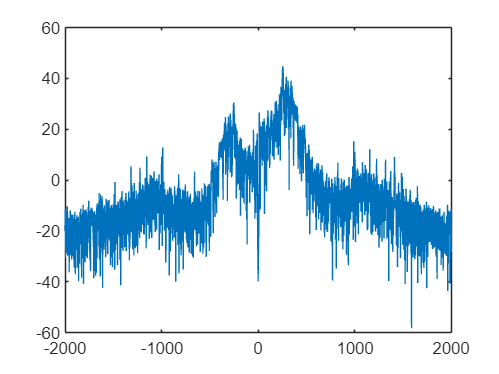

figure;
plot(f,S);
xlim([-2000 2000])

[max_amp, max_idx] = max(X);
f_d = f(max_idx);

if(f_d<10)
    v_rad=0;
else
    v_rad=c*f_d/(2*f_radar);
end

disp(['Radiell hastighet: ', num2str(v_rad), ' m/s']);

Radiell hastighet: 1.574 m/s


disp(['Dopplerskift: ', num2str(f_d), ' Hz']);

Dopplerskift: 253.2005 Hz
